**Loading CSV data files containing the data points extracted from the curves:**

TxData = readmatrix("C:\Users\Sarah Rusch\OneDrive\Desktop\Skripsie\Matlab\Graph Analysis\Rx.csv");
TyData = readmatrix("C:\Users\Sarah Rusch\OneDrive\Desktop\Skripsie\Matlab\Graph Analysis\Ry.csv");
TzData = readmatrix("C:\Users\Sarah Rusch\OneDrive\Desktop\Skripsie\Matlab\Graph Analysis\Rz.csv");

**Extract the time and amplitudes from each data set:**

TxT = TxData(:, 1);     % time data
TxX = TxData(:, 2);     % X amplitude data
TyT = TyData(:, 1);     % time data
TyY = TyData(:, 2);     % Y amplitude data
TzT = TzData(:, 1);     % time data
TzZ = TzData(:, 2);     % Z amplitude data

**Sort the data and remove duplicate data points:**

[TxT_sorted, sortIdxTxT] = sort(TxT);
TxX_sorted = TxX(sortIdxTxT);
[TxT_unique, idxTxT] = unique(TxT_sorted);
TxX_unique = TxX_sorted(idxTxT);

[TyT_sorted, sortIdxTyT] = sort(TyT);
TyY_sorted = TyY(sortIdxTyT);
[TyT_unique, idxTyT] = unique(TyT_sorted);
TyY_unique = TyY_sorted(idxTyT);

[TzT_sorted, sortIdxTzT] = sort(TzT);
TzZ_sorted = TzZ(sortIdxTzT);
[TzT_unique, idxTzT] = unique(TzT_sorted);
TzZ_unique = TzZ_sorted(idxTzT);

**Make a uniform time base for extracted data:**

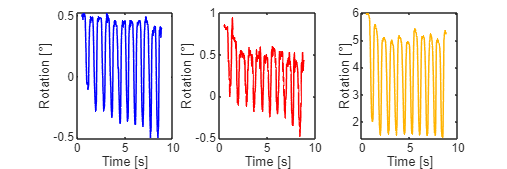

FsTx = 1 / mean(diff(TxT_unique));
TxT_uniform = linspace(min(TxT_unique), max(TxT_unique), length(TxT_unique));
TxX_uniform = interp1(TxT_unique, TxX_unique, TxT_uniform, 'linear');

FsTy = 1 / mean(diff(TyT_unique));
TyT_uniform = linspace(min(TyT_unique), max(TyT_unique), length(TyT_unique));
TyY_uniform = interp1(TyT_unique, TyY_unique, TyT_uniform, 'linear');

FsTz = 1 / mean(diff(TzT_unique));
TzT_uniform = linspace(min(TzT_unique), max(TzT_unique), length(TzT_unique));
TzZ_uniform = interp1(TzT_unique, TzZ_unique, TzT_uniform, 'linear');


figure('Position', [100, 100, 1200, 400]);

subplot(1,3,1)
plot(TxT_uniform, TxX_uniform, 'b-', 'LineWidth', 1)
hold on
xlabel('Time [s]')
ylabel('Rotation [°]')
hold off
subplot(1,3,2)
plot(TyT_uniform, TyY_uniform, 'r-', 'LineWidth', 1)
hold on
xlabel('Time [s]')
ylabel('Rotation [°]')
hold off
subplot(1,3,3)
plot(TzT_uniform, TzZ_uniform, 'y-', 'LineWidth', 1, 'Color', [1 0.7 0])
hold on
xlabel('Time [s]')
ylabel('Rotation [°]')
hold off

**Fourier Analysis:**

% X
LTxX = length(TxX_uniform);         % Number of points
X = fft(TxX_uniform);               % Compute FFT
P2X = abs(X/LTxX);                  % Two-sided spectrum
P1X = P2X(1:floor(LTxX/2)+1);       % Single-sided spectrum
P1X(2:end-1) = 2*P1X(2:end-1);
fX = FsTx*(0:floor(LTxX/2))/LTxX;   % Frequency axis

% Y
LTyY = length(TyY_uniform);         % Number of points
Y = fft(TyY_uniform);               % Compute FFT
P2Y = abs(Y/LTyY);                  % Two-sided spectrum
P1Y = P2Y(1:floor(LTyY/2)+1);       % Single-sided spectrum
P1Y(2:end-1) = 2*P1Y(2:end-1);
fY = FsTy*(0:floor(LTyY/2))/LTyY;   % Frequency axis

% Z
LTzZ = length(TzZ_uniform);         % Number of points
Z = fft(TzZ_uniform);               % Compute FFT
P2Z = abs(Z/LTzZ);                  % Two-sided spectrum
P1Z = P2Z(1:floor(LTzZ/2)+1);       % Single-sided spectrum
P1Z(2:end-1) = 2*P1Z(2:end-1);
fZ = FsTz*(0:floor(LTzZ/2))/LTzZ;   % Frequency axis

% X analysis
[peakX, FlocationX] = findpeaks(P1X, fX, 'MinPeakHeight', max(P1X)*0.01);
[~, max_peak_idx] = max(peakX);                % Find index of highest peak
fundamental_freqX = FlocationX(max_peak_idx);  % Get frequency of highest peak
tolX = 0.1 * fundamental_freqX;                % Tolerance
harmonicsX = [];
for k = 2:5                                    % Check up to 5 harmonics
    targetX = k * fundamental_freqX;
    % Find closest peak near interger multiple
    [~, idxX] = min(abs(FlocationX - targetX));
    if abs(FlocationX(idxX) - targetX) < tolX
        harmonicsX = [harmonicsX; FlocationX(idxX) peakX(idxX)];
    end
end
disp(['Fundamental frequency [X]: ', num2str(fundamental_freqX), ' Hz'])

Fundamental frequency [X]: 1.2002 Hz


disp('Harmonics (freq, amplitude) [X]:')

Harmonics (freq, amplitude) [X]:


disp(harmonicsX)

    2.5203    0.0940
    3.7205    0.0326
    4.9206    0.0208




% Y analysis
[peakY, FlocationY] = findpeaks(P1Y, fY, 'MinPeakHeight', max(P1Y)*0.01);
[~, max_peak_idx] = max(peakY);                % Find index of highest peak
fundamental_freqY = FlocationY(max_peak_idx);  % Get frequency of highest peak
tolY = 0.1 * fundamental_freqY;                % Tolerance
harmonicsY = [];
for l = 2:5                                    % Check up to 5 harmonics
    targetY = l * fundamental_freqY;
    % Find closest peak near target
    [~, idxY] = min(abs(FlocationY - targetY));
    if abs(FlocationY(idxY) - targetY) < tolY
        harmonicsY = [harmonicsY; FlocationY(idxY) peakY(idxY)];
    end
end
disp(['Fundamental frequency [Y]: ', num2str(fundamental_freqY), ' Hz'])

Fundamental frequency [Y]: 1.2004 Hz


disp('Harmonics (freq, amplitude) [Y]:')

Harmonics (freq, amplitude) [Y]:


disp(harmonicsY)

    2.5208    0.0863
    3.7211    0.0258
    4.8014    0.0110




% Z analysis
[peakZ, FlocationZ] = findpeaks(P1Z, fZ, 'MinPeakHeight', max(P1Z)*0.01);
[~, max_peak_idx] = max(peakZ);                % Find index of highest peak
fundamental_freqZ = FlocationZ(max_peak_idx);  % Get frequency of highest peak
tolZ = 0.1 * fundamental_freqZ;                % Tolerance
harmonicsZ = [];
for m = 2:5                                    % Check up to 5 harmonics
    targetZ = m * fundamental_freqZ;    
    % Find closest peak near target
    [~, idxZ] = min(abs(FlocationZ - targetZ));
    if abs(FlocationZ(idxZ) - targetZ) < tolZ
        harmonicsZ = [harmonicsZ; FlocationZ(idxZ) peakZ(idxZ)];
    end
end
disp(['Fundamental frequency [Z]: ', num2str(fundamental_freqZ), ' Hz'])

Fundamental frequency [Z]: 1.2006 Hz


disp('Harmonics (freq, amplitude) [Z]:')

Harmonics (freq, amplitude) [Z]:


disp(harmonicsZ)

    2.4012    0.3479
    3.7219    0.1076



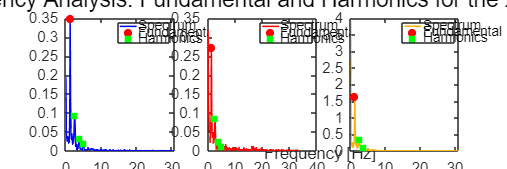


figure('Position', [100, 100, 1200, 400]); 

% X plot
subplot(1,3,1)
plot(fX, P1X, 'b-', 'LineWidth', 1)
hold on
[~, fund_idx_x] = min(abs(fX - fundamental_freqX));
plot(fundamental_freqX, P1X(fund_idx_x), 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');
if ~isempty(harmonicsX)
    for i = 1:size(harmonicsX, 1)
        [~, harm_idx] = min(abs(fX - harmonicsX(i,1)));
        plot(harmonicsX(i,1), P1X(harm_idx), 'gs', 'MarkerSize', 5, 'MarkerFaceColor', 'g');
    end
end
xlabel('Frequency [Hz]')
ylabel('Amplitude')
legend('Spectrum', 'Fundamental', 'Harmonics')
hold off

% Y plot
subplot(1,3,2)
plot(fY, P1Y, 'r-', 'LineWidth', 1)
hold on
[~, fund_idx_y] = min(abs(fY - fundamental_freqY));
plot(fundamental_freqY, P1Y(fund_idx_y), 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');
if ~isempty(harmonicsY)
    for i = 1:size(harmonicsY, 1)
        [~, harm_idx] = min(abs(fY - harmonicsY(i,1)));
        plot(harmonicsY(i,1), P1Y(harm_idx), 'gs', 'MarkerSize', 5, 'MarkerFaceColor', 'g');
    end
end
xlabel('Frequency [Hz]')
ylabel('Amplitude')
legend('Spectrum', 'Fundamental', 'Harmonics')
hold off

% Z plot
subplot(1,3,3)
plot(fZ, P1Z, 'y-', 'LineWidth', 1, 'Color', [1 0.7 0]) % Orange color
hold on
[~, fund_idx_z] = min(abs(fZ - fundamental_freqZ));
plot(fundamental_freqZ, P1Z(fund_idx_z), 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');
if ~isempty(harmonicsZ)
    for i = 1:size(harmonicsZ, 1)
        [~, harm_idx] = min(abs(fZ - harmonicsZ(i,1)));
        plot(harmonicsZ(i,1), P1Z(harm_idx), 'gs', 'MarkerSize', 5, 'MarkerFaceColor', 'g');
    end
end
xlabel('Frequency [Hz]')
ylabel('Amplitude')
legend('Spectrum', 'Fundamental', 'Harmonics')
hold off

% Add overall title
sgtitle('Rotation Frequency Analysis: Fundamental and Harmonics for the X, Y and Z Axes')


% Get the fundamental amplitudes for each axis
fund_amp_X = interp1(fX, P1X, fundamental_freqX)

fund_amp_X = 0.3492

fund_amp_Y = interp1(fY, P1Y, fundamental_freqY)

fund_amp_Y = 0.2717

fund_amp_Z = interp1(fZ, P1Z, fundamental_freqZ)

fund_amp_Z = 1.6242


% Find the maximum fundamental amplitude
max_fundamental_amp = max([fund_amp_X, fund_amp_Y, fund_amp_Z])

max_fundamental_amp = 1.6242


% Calculate relative amplitudes as percentages
rel_amp_X = (fund_amp_X / (fund_amp_X + fund_amp_Y + fund_amp_Z) ) * 100

rel_amp_X = 15.5547

rel_amp_Y = (fund_amp_Y / (fund_amp_X + fund_amp_Y + fund_amp_Z) ) * 100

rel_amp_Y = 12.1036

rel_amp_Z = (fund_amp_Z / (fund_amp_X + fund_amp_Y + fund_amp_Z) ) * 100

rel_amp_Z = 72.3417

**Data Filtering:**

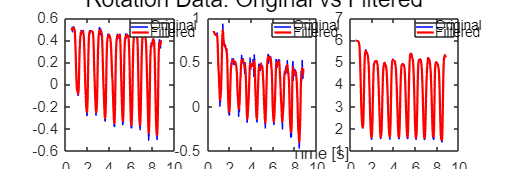

% Set filter parameters
filter_order = 1;  
cutoff_freq_ratiox = 0.2;  
cutoff_freq_ratioy = 0.2;
cutoff_freq_ratioz = 0.2;

% LPF design
[b_x, a_x] = butter(filter_order, cutoff_freq_ratiox, 'low');
[b_y, a_y] = butter(filter_order, cutoff_freq_ratioy, 'low');
[b_z, a_z] = butter(filter_order, cutoff_freq_ratioz, 'low');

% Apply LPFs
TxX_filtered = filtfilt(b_x, a_x, TxX_uniform);
TyY_filtered = filtfilt(b_y, a_y, TyY_uniform);
TzZ_filtered = filtfilt(b_z, a_z, TzZ_uniform);

% Plot original and filtered data
% X
figure('Position', [100, 100, 1200, 400]);
subplot(1,3,1)
plot(TxT_uniform, TxX_uniform, 'b-', 'LineWidth', 0.5, 'DisplayName', 'Original');
hold on;
plot(TxT_uniform, TxX_filtered, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Filtered');
xlabel('Time [s]'); 
ylabel('Rotation [°]');
legend; 
hold off;
% Y
subplot(1,3,2)
plot(TyT_uniform, TyY_uniform, 'b-', 'LineWidth', 0.5, 'DisplayName', 'Original');
hold on;
plot(TyT_uniform, TyY_filtered, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Filtered');
xlabel('Time [s]'); 
ylabel('Rotation [°]');
legend; 
hold off;
% Z
subplot(1,3,3)
plot(TzT_uniform, TzZ_uniform, 'b-', 'LineWidth', 0.5, 'DisplayName', 'Original');
hold on;
plot(TzT_uniform, TzZ_filtered, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Filtered');
xlabel('Time [s]'); 
ylabel('Rotation [°]');
legend;
hold off;

sgtitle('Rotation Data: Original vs Filtered');

**Velocity and Acceleration Analysis:**

% Calculate time steps
dt_x = mean(diff(TxT_uniform));
dt_y = mean(diff(TyT_uniform));
dt_z = mean(diff(TzT_uniform));

% Calculate velocities
TxX_velocity = gradient(TxX_filtered, dt_x);
TyY_velocity = gradient(TyY_filtered, dt_y);
TzZ_velocity = gradient(TzZ_filtered, dt_z); 

% Calculate accelerations
TxX_acceleration = gradient(TxX_velocity, dt_x);
TyY_acceleration = gradient(TyY_velocity, dt_y); 
TzZ_acceleration = gradient(TzZ_velocity, dt_z);  

Graphs:

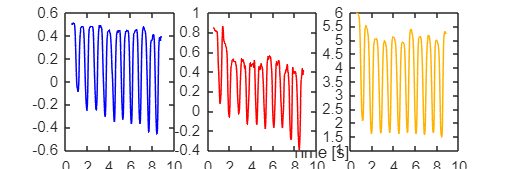

% Displacement plots
figure('Position', [100, 100, 1200, 400]);
% X
subplot(1,3,1); 
plot(TxT_uniform, TxX_filtered, 'b-', 'LineWidth', 1); 
xlabel('Time [s]'); 
ylabel('Rotation [°]');
% Y
subplot(1,3,2); 
plot(TyT_uniform, TyY_filtered, 'r-', 'LineWidth', 1); 
xlabel('Time [s]');
ylabel('Rotation [°]');
% Z
subplot(1,3,3); 
plot(TzT_uniform, TzZ_filtered, 'Color', [1 0.7 0], 'LineWidth', 1); 
xlabel('Time [s]');
ylabel('Rotation [°]');

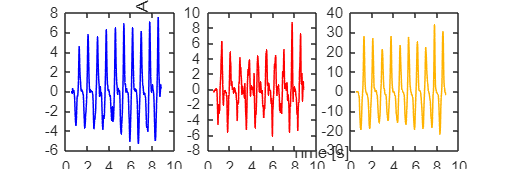


% Velocity plots
figure('Position', [100, 100, 1200, 400]);
% X
subplot(1,3,1); 
plot(TxT_uniform, TxX_velocity, 'b-', 'LineWidth', 1); 
xlabel('Time [s]');
ylabel('Angular Velocity [°/s]');
% Y
subplot(1,3,2); 
plot(TyT_uniform, TyY_velocity, 'r-', 'LineWidth', 1); 
xlabel('Time [s]');
ylabel('Angular Velocity [°/s]');
% Z
subplot(1,3,3); 
plot(TzT_uniform, TzZ_velocity, 'Color', [1 0.7 0], 'LineWidth', 1); 
xlabel('Time [s]');
ylabel('Angular Velocity [°/s]');

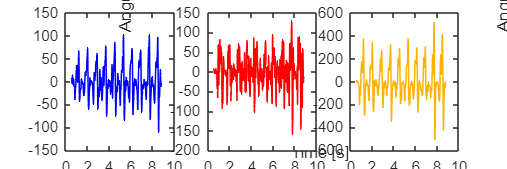


% Acceleration plots
figure('Position', [100, 100, 1200, 400]);
% X
subplot(1,3,1); 
plot(TxT_uniform, TxX_acceleration, 'b-', 'LineWidth', 1); 
xlabel('Time [s]');
ylabel('Angular Acceleration [°/s²]');
% Y
subplot(1,3,2); 
plot(TyT_uniform, TyY_acceleration, 'r-', 'LineWidth', 1); 
xlabel('Time [s]');
ylabel('Angular Acceleration [°/s²]');
% Z
subplot(1,3,3); 
plot(TzT_uniform, TzZ_acceleration, 'Color', [1 0.7 0], 'LineWidth', 1); 
xlabel('Time [s]');
ylabel('Angular Acceleration [°/s²]');

Maximum and minimum values:

% Velocity
vel_max_X = max(TxX_velocity);
vel_min_X = min(TxX_velocity);
vel_max_Y = max(TyY_velocity);
vel_min_Y = min(TyY_velocity);
vel_max_Z = max(TzZ_velocity);
vel_min_Z = min(TzZ_velocity);

% Acceleration
accel_max_X = max(TxX_acceleration);
accel_min_X = min(TxX_acceleration);
accel_max_Y = max(TyY_acceleration);
accel_min_Y = min(TyY_acceleration);
accel_max_Z = max(TzZ_acceleration);
accel_min_Z = min(TzZ_acceleration);

fprintf('Velocity Max & Min:\n');

Velocity Max & Min:


fprintf('  X: Max=%.6f, Min=%.6f mm/s\n', vel_max_X, vel_min_X);

  X: Max=7.529946, Min=-5.305124 mm/s


fprintf('  Y: Max=%.6f, Min=%.6f mm/s\n', vel_max_Y, vel_min_Y);

  Y: Max=8.706359, Min=-6.112611 mm/s


fprintf('  Z: Max=%.6f, Min=%.6f mm/s\n', vel_max_Z, vel_min_Z);

  Z: Max=33.716124, Min=-21.669190 mm/s



fprintf('\nAcceleration Max & Min:\n');


Acceleration Max & Min:


fprintf('  X: Max=%.6f, Min=%.6f mm/s²\n', accel_max_X, accel_min_X);

  X: Max=102.111287, Min=-110.913831 mm/s²


fprintf('  Y: Max=%.6f, Min=%.6f mm/s²\n', accel_max_Y, accel_min_Y);

  Y: Max=128.503779, Min=-159.379835 mm/s²


fprintf('  Z: Max=%.6f, Min=%.6f mm/s²\n', accel_max_Z, accel_min_Z);

  Z: Max=511.602476, Min=-502.773114 mm/s²
